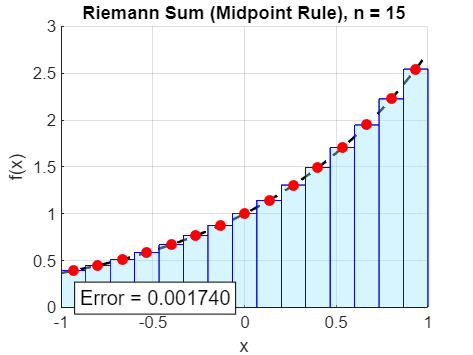

clc; clear;

% Function to integrate
f = @(x) exp(x);  % Try others like sin(pi*x), exp(-x.^2), etc.

% Domain
a = -1; b = 1;

% Exact integration
I_exact = integral(f, a, b, 'AbsTol', 1e-12, 'RelTol', 1e-12);

% Loop over increasing number of rectangles
for n = 2:15
    x = linspace(a, b, n+1);           % Edges
    dx = (b - a) / n;                  % Width of each rectangle
    midpoints = (x(1:end-1) + x(2:end)) / 2;
    heights = f(midpoints);           % f at midpoint

    % Plot setup
    figure(1); clf; hold on; grid on;
    fplot(f, [a, b], 'k--', 'LineWidth', 1.5);
    xlabel('x'); ylabel('f(x)');
    title(['Riemann Sum (Midpoint Rule), n = ', num2str(n)]);

    % Draw rectangles
    for i = 1:n
        x_left = x(i);
        x_right = x(i+1);
        x_rect = [x_left, x_right, x_right, x_left];
        y_rect = [0, 0, heights(i), heights(i)];

        fill(x_rect, y_rect, [0.6 0.9 1], 'EdgeColor', 'b', 'FaceAlpha', 0.4);
    end

    % Plot midpoint markers
    plot(midpoints, heights, 'ro', 'MarkerFaceColor', 'r');

    % Display approximation
    I_approx = sum(heights * dx);
    text(a + 0.1, 0.1, sprintf('Error = %.6f', abs(I_approx-I_exact)), ...
        'FontSize', 12, 'BackgroundColor', 'w', 'EdgeColor', 'k');

    pause(1.2);  % Wait before next n
end